a={};
b=[];


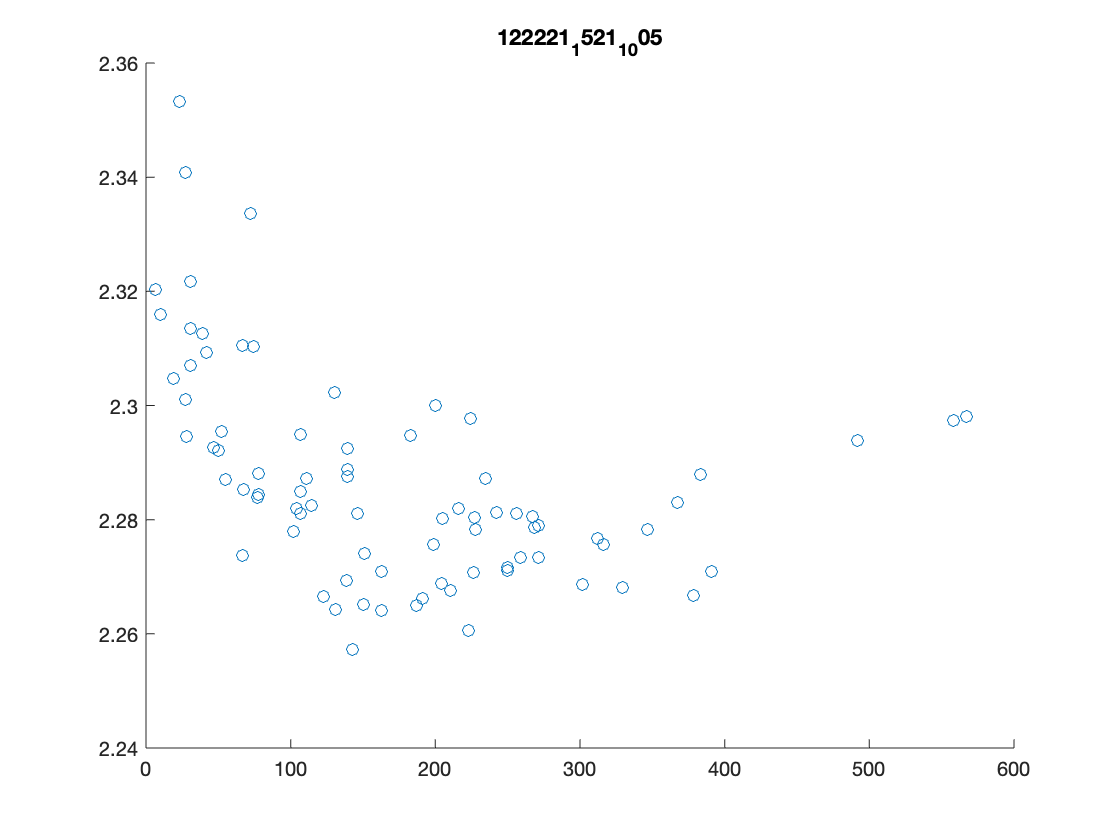


c=zeros(size(b,1),1);

for i=1:size(b,1)
    c(i)=a{i}(2)-a{i}(1);
end

figure
scatter(c,b)
title(ExperimentName)

figure
heatmap(cdata)
colorbar
ax = axes;
plot(ax,magic(4),'LineWidth',2)
ax.Color = 'none';



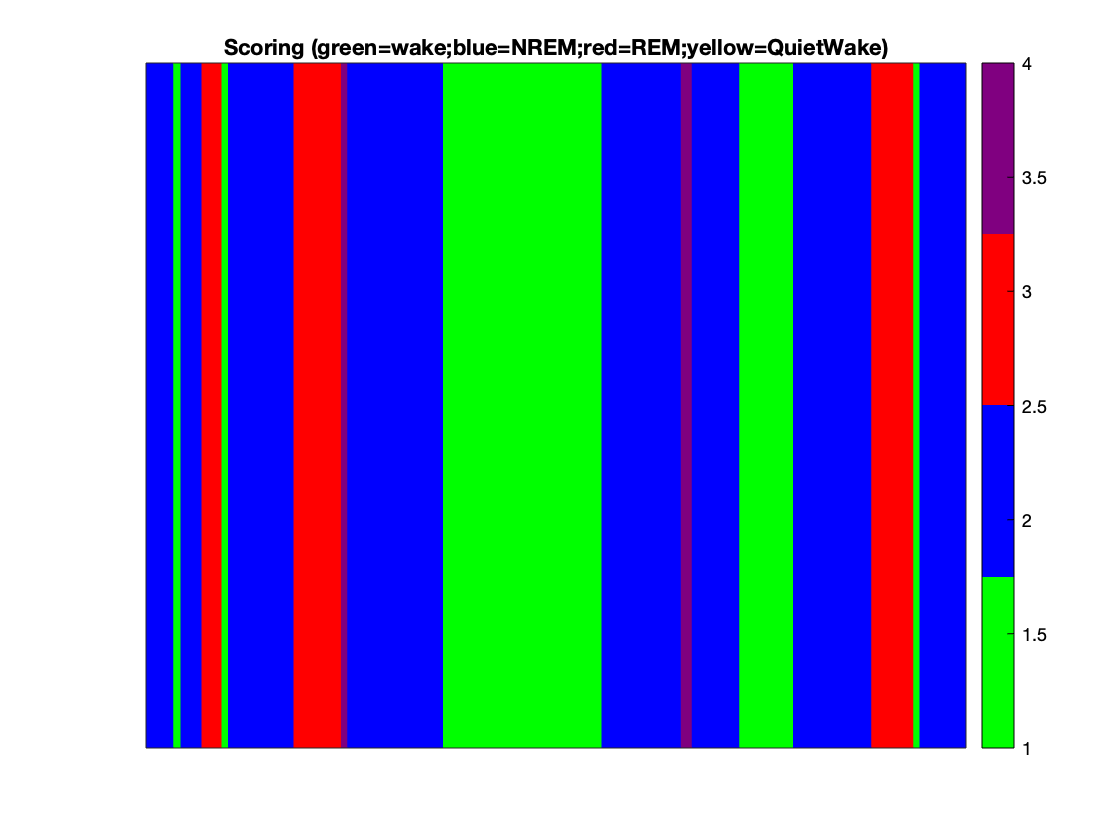

figure
ScoringHeatMap=heatmap(states_14h','Colormap',[0 1 0;0 0 1;1 0 0;.5 0 .5],...
    'GridVisible','off',...
    'FontColor',[0 0 0],...
    'ColorLimits',[1 4],...
    'Title','Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');
ScoringHeatMap.YDisplayLabels=repmat(' ', 1, 1);
ScoringHeatMap.XDisplayLabels=repmat(' ', 900, 1);

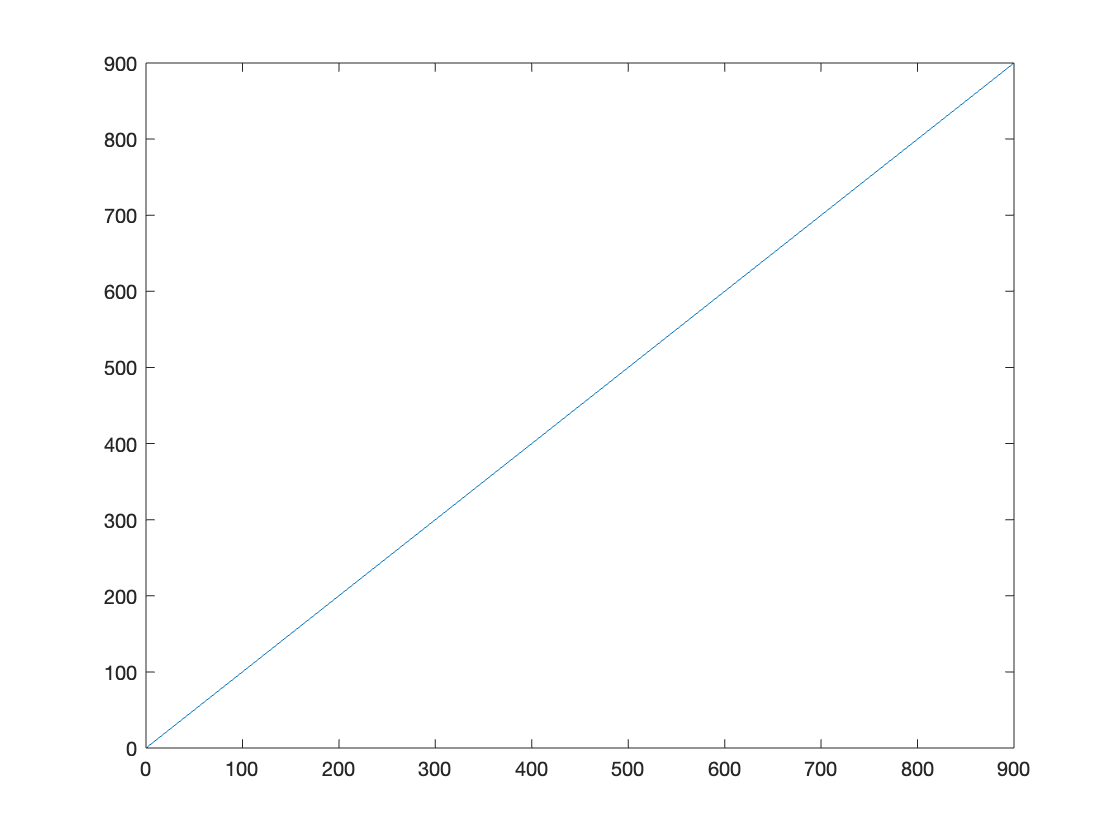


plot(1:1:900)

median_time=[];

for i=1:size(test,1)
    this_epoch=tau_empTrunc_all_DC_darkonly(test(i,1):test(i,2));
    [med,I]=sort(this_epoch);
    if rem(size(this_epoch,1),2)==1
        this_median=I((size(this_epoch,1)+1)/2)+double(test(i,1));
    else
        this_median=[I(size(this_epoch,1)/2) I(size(this_epoch,1)/2+1)]+double(test(i,1));
    end
    
    median_time=[median_time this_median];
end



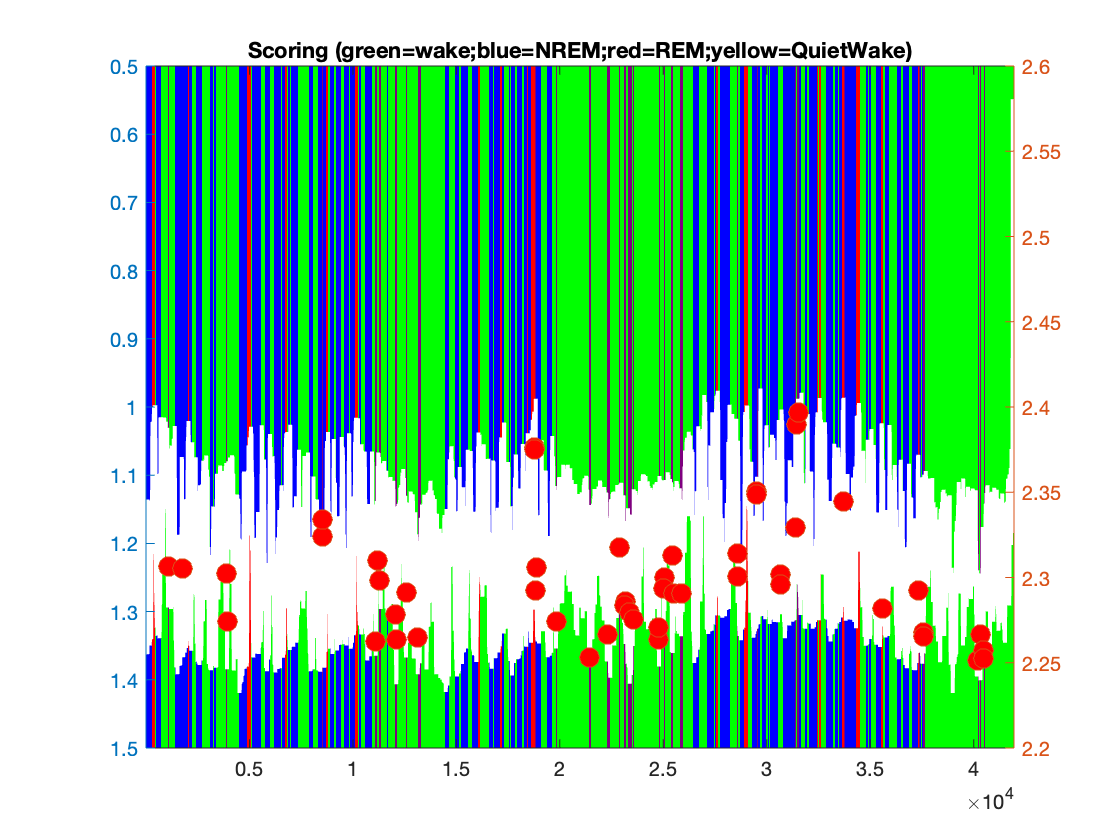


figure
yyaxis left
imagesc(states_for_time_all_dark')
colormap([0 1 0;0 0 1;1 0 0;.5 0 .5])
title('Scoring (green=wake;blue=NREM;red=REM;yellow=QuietWake)');




yyaxis right
plot(tau_empTrunc_all_darkonly,'LineWidth',2,'Color','white')
hold on
yyaxis right
plot(median_time,tau_empTrunc_all_darkonly(median_time)','o','MarkerSize',10,'MarkerFaceColor','Red')